
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
maxSpeed = 0.1; 
timeStep = 10; 

% Initial states. 
initialStates = [-1; 0; 1; 0; 1; 0; 0; 1]; 

% Position constraints. 
positionBounds = [-1; 1; -1; 1]*50; 

% TPBVP test time span input. 
tspan = 0 : 1E-2 : timeStep; 

% Initial guess. 
guess = [ ...
    y_a(1:8)-initialStates; ...
    y_b(9:16) - [ ...
    y_b(1)-y_b(3); ...
    y_b(2)-y_b(4); ...
    -(y_b(1)-y_b(3)); ...
    -(y_b(2)-y_b(4)); ...
    zeros(4, 1)]]; 

solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, droneSpeed), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b,  x_c_0, x_e_0, timeStep), ...
    solGuess, options); 

The solution was obtained on a mesh of 1001 points.
The maximum residual is  5.083e-07. 
There were 24232 calls to the ODE function. 
There were 39 calls to the BC function. 


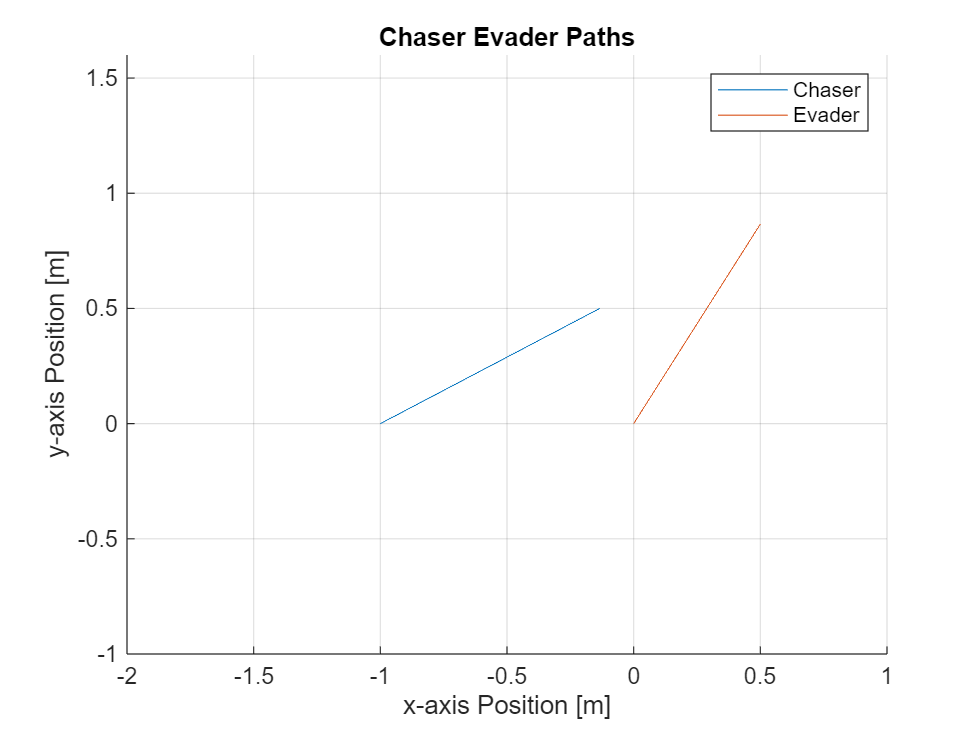

tspan = sol.x; 
y = sol.y; 
chaserPath = y(1:2, :); 
evaderPath = y(3:4, :); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :), evaderPath(1, :), evaderPath(2, :)); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
axis([-2 1 -1 1.6]); 
hold off;  

% Differential equations. 
function dydt = eqns(~, y, maxSpeed, pBnds)
    % Optimal control. 
    % S_1 = (y(13)^2+y(14)^2) < maxSpeed^2; 
    % S_2 = (y(15)^2+y(16)^2) < maxSpeed^2; 
    % u = [ ...
    %     S_1*-y(13) + ~S_1*-maxSpeed*y(13)/sqrt(y(13)^2+y(14)^2); ...
    %     S_1*-y(14) + ~S_1*-maxSpeed*y(14)/sqrt(y(13)^2+y(14)^2); ...
    %     S_2*y(15) + ~S_2*maxSpeed*y(15)/sqrt(y(15)^2+y(16)^2); ...
    %     S_2*y(16) + ~S_2*maxSpeed*y(16)/sqrt(y(15)^2+y(16)^2)]; 
    nu = max([ ...
        0.5*(sqrt(y(13)^2+y(14)^2)/maxSpeed-1); ...
        0.5*(1-sqrt(y(15)^2+y(16)^2)/maxSpeed)], 0); 
    u = [ ...
        -y(13)/(1+2*nu(1)); ...
        -y(14)/(1+2*nu(1)); ...
        y(15)/(1-2*nu(2)); ...
        y(16)/(1-2*nu(2))]; 

    % Position and velocity constraints. 
    mu = max([ ...
        pBnds(1)-y(1); ...
        y(1)-pBnds(2); ...
        pBnds(3)-y(2); ...
        y(2)-pBnds(4); ...
        pBnds(1)-y(3); ...
        y(3)-pBnds(2); ...
        pBnds(3)-y(4); ...
        y(4)-pBnds(4)], 0); 

    A = [zeros(4) eye(4); zeros(4) zeros(4)]; 
    B = [zeros(4); eye(4)]; 
    dydt = [ ...
        A*y+B*u; ...
        mu(1)-mu(2); ...
        mu(3)-mu(4); ...
        mu(5)-mu(6); ...
        mu(7)-mu(8); ...
        -y(9:12)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, initialStates)
    retval = [ ...
        y_a(1:8)-initialStates; ...
        y_b(9:16) - [ ...
        y_b(1)-y_b(3); ...
        y_b(2)-y_b(4); ...
        -(y_b(1)-y_b(3)); ...
        -(y_b(2)-y_b(4)); ...
        zeros(4, 1)]]; 
end